## Load ECG Data from parent directory

%% Load ECG Data from parent directory
cd ..
clear,clc
load('mitdb_dataset.mat')
cd ./PCA

## Load Noise file, Find R-Peaks, Calculate RR-Intervals

load('em_noise.mat')
numRecords = size(ecg,1);
%numExperiments = 1;
rrInterval = cell(numRecords,1);
rr_tm = cell(numRecords,1);

%%%%% THE FOLLOWING LOOP DEPENDS ON THE PQRST DECTECTION TOOLBOX which
%%%%% contains the pan_tompkin2 function
%{
R. Sanghavi, F. Chheda, S. Kanchan and S. Kadge, 
"Detection Of Atrial Fibrillation in Electrocardiogram Signals using Machine Learning," 
2021 2nd Global Conference for Advancement in Technology (GCAT), 2021, pp. 1-6, doi: 10.1109/GCAT52182.2021.9587664.
%}
for i = 1:numRecords
    [~, rr_tm{i,1},~] = pan_tompkin2(ecg{i,1},Fs(i));
    rrInterval{i,1} = zeros(1,length(rr_tm{i,1})-1);
    for z = 1:length(rrInterval{i,1})-1
        rrInterval{i,1}(z) = rr_tm{i,1}(z+1) - rr_tm{i,1}(z);
    end
end

## Noise Generation and Pre-Allocating Variables for Results

Experiments = ["Gaussian12dB","0.1EM","Gaussian6dB","0.2EM","Gaussian2dB","0.3EM"];
%windowOptions = 3:36:1200;
k = 1;
window=3; % window size 3 chosen to maximize SNR_imp
%
numExperiments = 6;
%numExperiments = length(windowOptions);
numExpRecords = numRecords;
%numExpRecords = 1;

gaussianSNRs = [12 6 2];
EM_scales = [.1 .2 .3];
%snr =  gaussianSNRs(2);
%scale = EM_scales(2);

snr_imp = zeros(numExpRecords,numExperiments); %Final Performance metric, measured in PCA_denoising function
%Allocate space to store short samples of clean, noisy, and denoised
%versions of all patients
denoisedSignal2Plot = cell(numExpRecords,numExperiments); 
noisySignal2Plot = denoisedSignal2Plot;
varianceExplained = denoisedSignal2Plot;
origSignal2Plot = cell(numExpRecords,1);

%Specify the length of the samples to store
sampleRange = 360:2160;

tic

% Loop through all patients
% Load signal, rr_intervals, and rPeakStamps from each
for i = 1:numExpRecords
    recNum = i; % Can select number between 1 and 23 to access MIT database
    expNum = 1;
    these_rr_ints = rrInterval{recNum,1};
    rPeakStamps = rr_tm{recNum,1};
    ecgTrue = ecg{recNum,1};
    origSignal2Plot{recNum,1} = ecgTrue(sampleRange);

    % Each loop here performs 2 of the 6 experiments
    for j = 1:3
    %for j = 1:numExperiments
        snr = gaussianSNRs(j);
        scale = EM_scales(j);
        %expNum = j;
        %window = windowOptions(j);

        %Generate both Gaussian and EM noised versions of signal: 
        [noisyECG, ~] = createSignalPlusNoise(ecgTrue,snr);
        noisyECG2 = ecgTrue+scale*em_noise;

        %Call PCA_denoisingMIT function on Gaussian
        [denoisedSignal2Plot{recNum,expNum},snr_imp(recNum,expNum),varianceExplained{recNum,expNum}] = PCA_denoisingMIT(noisyECG,...
            ecgTrue,these_rr_ints,rPeakStamps,window,k,sampleRange);
        noisySignal2Plot{recNum,expNum} = noisyECG(sampleRange);
        expNum=expNum+1; %Increment experiment number
        
        %Call PCA_denoisingMIT function on EM
        [denoisedSignal2Plot{recNum,expNum},snr_imp(recNum,expNum),varianceExplained{recNum,expNum}] = PCA_denoisingMIT(noisyECG2,...
            ecgTrue,these_rr_ints,rPeakStamps,window,k,sampleRange);
        noisySignal2Plot{recNum,expNum} = noisyECG2(sampleRange);
        expNum=expNum+1;
    end
end

%%%% Due to the dimensions of data matrix (and inclusion of constant padded
%%%% values), it is expected to see a warning message similar to the following:

%"Warning: Columns of X are linearly dependent to within machine precision.
%Using only the first ___ components to compute TSQUARED."
toc %on a Dell Precision, the entire script runs in about 180-200 seconds.

Elapsed time is 206.580613 seconds.


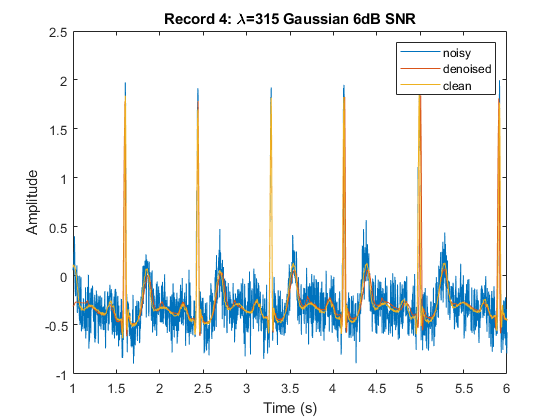

%%%%% This section can be used to explore results from experiment. Change
%%%%% "patient" to select patient between 1 and 48. Change "experiment" to
%%%%% toggle between different noise levels
figure
lam = num2str(window);
patient = 4; %Can pick number between 1 and 48;
experiment = 3; % 1: GN12dB | 2: .1EM | 3: GN6dB | 4: .2EM | 5: GN2dB | 6: .3EM
extoggle = ["Gaussian 12dB SNR",".1 EM","Gaussian 6dB SNR",".2 EM","Gaussian 2dB SNR",".3 EM"];
titstring = strcat("Record ",num2str(patient),": \lambda=",lam," ",extoggle(experiment));
plot(sampleRange./360, noisySignal2Plot{patient,experiment})
hold on
plot(sampleRange./360, denoisedSignal2Plot{patient,experiment})
plot(sampleRange./360 , origSignal2Plot{patient,1})
legend('noisy','denoised','clean')
title(titstring)
xlabel('Time (s)')
ylabel('Amplitude')

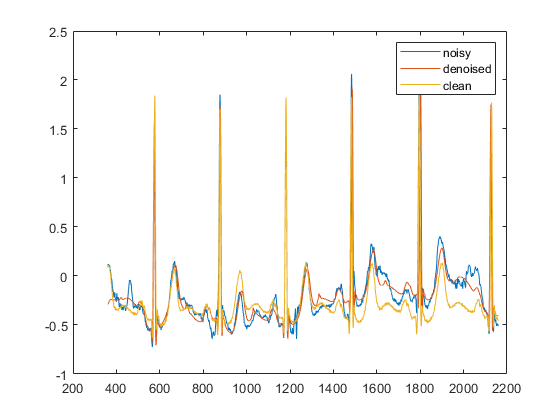

%{
figure
plot(sampleRange, noisySignal2Plot{4,6})
hold on
plot(sampleRange, denoisedSignal2Plot{4,6})
plot(sampleRange, origSignal2Plot{4,1})
legend('noisy','denoised','clean')

%}

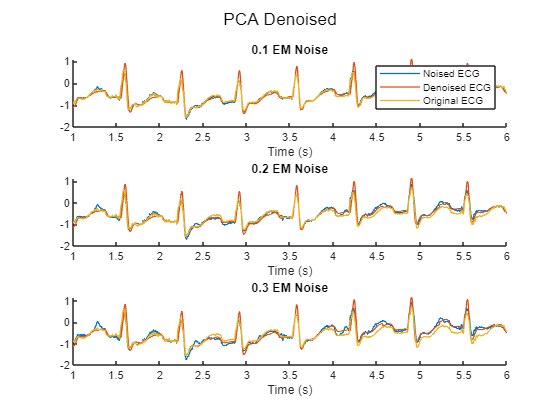

%%%%% PLOT RESULTS %%%%%
figure; 
sgtitle('PCA Denoised')
i = 10; 
fs = Fs(i);
t = sampleRange/fs;
expNum = 2;
orig_sig = origSignal2Plot{i,1};
orig_sig_plus_noise = noisySignal2Plot{i,expNum};
den_sig = denoisedSignal2Plot{i,expNum};

subplot(3,1,1)


hold on; 
plot(t,orig_sig_plus_noise,'LineWidth',1);
plot(t,den_sig,'LineWidth',1);
plot(t,orig_sig,'LineWidth',1);
xlim([1,6]);
xlabel('Time (s)')
legend('Noised ECG','Denoised ECG','Original ECG')
title('0.1 EM Noise')

subplot(3,1,2)
expNum = 4;
orig_sig_plus_noise = noisySignal2Plot{i,expNum};    
den_sig = denoisedSignal2Plot{i,expNum};
hold on; 
plot(t,orig_sig_plus_noise,'LineWidth',1);
plot(t,den_sig,'LineWidth',1);
plot(t,orig_sig,'LineWidth',1);
xlim([1,6]);
xlabel('Time (s)')
title('0.2 EM Noise')

subplot(3,1,3)
expNum = 6;
orig_sig_plus_noise = noisySignal2Plot{i,expNum};    
den_sig = denoisedSignal2Plot{i,expNum};
hold on; 
plot(t,orig_sig_plus_noise,'LineWidth',1);
plot(t,den_sig,'LineWidth',1);
plot(t,orig_sig,'LineWidth',1);
xlim([1,6]);
xlabel('Time (s)')
title('0.3 EM Noise')

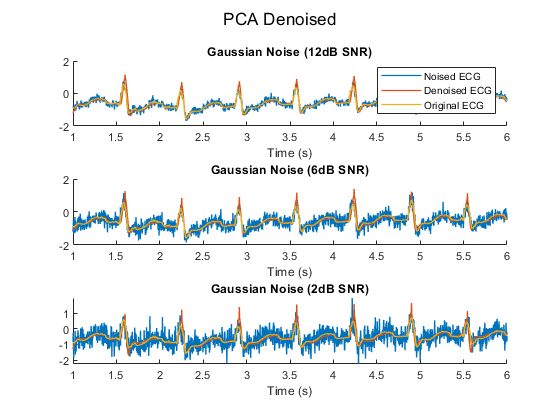

%%%%% PLOT GAUSSIAN RESULTS %%%%%
figure;
sgtitle('PCA Denoised')
i = 10; 
fs = Fs(i);
t = sampleRange/fs;
expNum = 1;
orig_sig = origSignal2Plot{i,1};
orig_sig_plus_noise = noisySignal2Plot{i,expNum};
den_sig = denoisedSignal2Plot{i,expNum};

subplot(3,1,1)
hold on; 
plot(t,orig_sig_plus_noise,'LineWidth',1);
plot(t,den_sig,'LineWidth',1);
plot(t,orig_sig,'LineWidth',1);
xlim([1,6]);
xlabel('Time (s)')
legend('Noised ECG','Denoised ECG','Original ECG')
title('Gaussian Noise (12dB SNR)')

subplot(3,1,2)
expNum = 3;
orig_sig_plus_noise = noisySignal2Plot{i,expNum};    
den_sig = denoisedSignal2Plot{i,expNum};
hold on; 
plot(t,orig_sig_plus_noise,'LineWidth',1);
plot(t,den_sig,'LineWidth',1);
plot(t,orig_sig,'LineWidth',1);
xlim([1,6]);
xlabel('Time (s)')
title('Gaussian Noise (6dB SNR)')

subplot(3,1,3)
expNum = 5;
orig_sig_plus_noise = noisySignal2Plot{i,expNum};    
den_sig = denoisedSignal2Plot{i,expNum};
hold on; 
plot(t,orig_sig_plus_noise,'LineWidth',1);
plot(t,den_sig,'LineWidth',1);
plot(t,orig_sig,'LineWidth',1);
xlim([1,6]);
xlabel('Time (s)')
title('Gaussian Noise (2dB SNR)')